# Part1

## Sampling rate adaptation

%1:
%% Given Parameters
f_s = 5;           % Symbol rate (Hz)
f_s_TX = 30;       % Transmitter DAC sampling rate (Hz)
f_s_RX = 7.5;      % Receiver ADC sampling rate (Hz)
L = f_s_TX / f_s;        % Upsampling factor 6
M = f_s_RX / f_s;     % Downsampling factor 1.5
fprintf('Upsampling factor L (symbols to DAC): %.1f\n', L);

Upsampling factor L (symbols to DAC): 6.0


fprintf('Downsampling factor M (ADC to symbols): %.1f\n', M);

Downsampling factor M (ADC to symbols): 1.5


fprintf('\n');

%2:
t_symbols_b = tSamp; % Time vector for symbols
symbols_b_real = real(Symbols); % Real part of symbols
symbols_b_length = length(Symbols);

symbols_b_length = 32

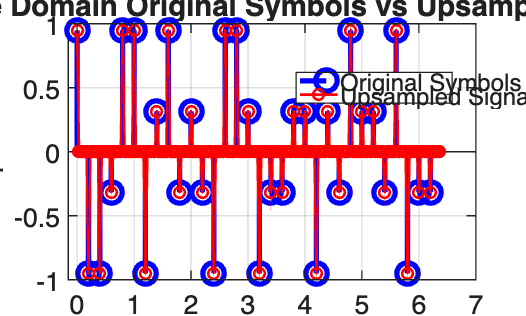

% Insert L-1 zeros between each symbol
symbols_c_length = length(Symbols) * L;%192
symbols_c = zeros(symbols_c_length, 1);
symbols_c(1:L:end) = Symbols; % Place symbols at every L-th position

% Time vector for upsampled signal
t_symbols_c = (0:length(symbols_c)-1) / f_s_TX;%192/30 = 6.4

% Plot time domain comparison
figure;
stem(t_symbols_b, symbols_b_real, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;
plot(t_symbols_c, real(symbols_c), 'ro-', 'LineWidth', 1, 'MarkerSize', 4);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('1-2: Time Domain Original Symbols vs Upsampled Signal');
legend('Original Symbols (b)', 'Upsampled Signal (c)', 'Location', 'best');
grid on;

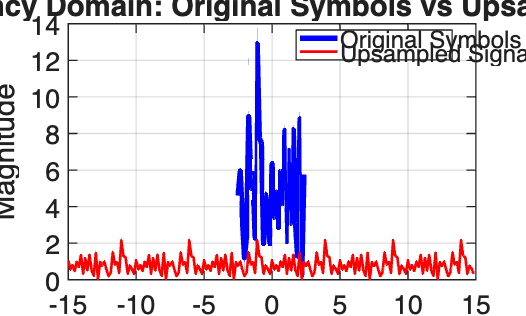

%3:
% FFT of original symbols
fft_b = fft(Symbols, symbols_b_length);
freq_b = (-symbols_b_length/2:symbols_b_length/2-1) * f_s / symbols_b_length;
X_b = fftshift(fft_b);
% FFT of upsampled signal  
fft_c = 1/L*fft(symbols_c, symbols_c_length);
freq_c = (-symbols_c_length/2:symbols_c_length/2-1) * f_s_TX / symbols_c_length;
X_c = fftshift(fft_c);
% Plot frequency domain comparison
figure;
plot(freq_b, abs(X_b), 'b-', 'LineWidth', 2);
hold on;
plot(freq_c, abs(X_c), 'r-', 'LineWidth', 1);
xlim([-15 15]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('1-3: Frequency Domain: Original Symbols vs Upsampled Signal');
legend('Original Symbols (b)', 'Upsampled Signal (c)', 'Location', 'best');
grid on;

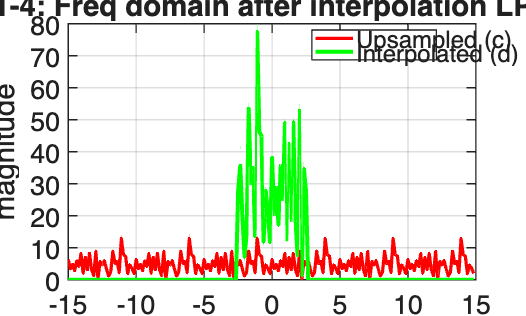

%4:
fc = f_s/2;% 2.5 Hz
%to freq domain
Xc = fftshift(fft(symbols_c));
freq_d = (-symbols_c_length/2:symbols_c_length/2-1) * (f_s_TX/symbols_c_length);% Hz

%filter multiplication in freq domain
H = double(abs(freq_d) <= fc) * L;
Xd = Xc .* H(:);

%back to time domain
d_long = ifft(ifftshift(Xd));
symbols_d = d_long(1:length(symbols_c));

%shift for plotting
X_d = fftshift(fft(symbols_d));

%plot the freq domain
figure;
plot(freq_d, abs(Xc), 'r','LineWidth',1.2); hold on;
plot(freq_d, abs(X_d), 'g','LineWidth',1.5);
xlim([-15 15]); grid on;
xlabel('Frequency (Hz)'); ylabel('magnitude');
legend('Upsampled (c)','Interpolated (d)','Location','best');
title('1-4: Freq domain after interpolation LPF');

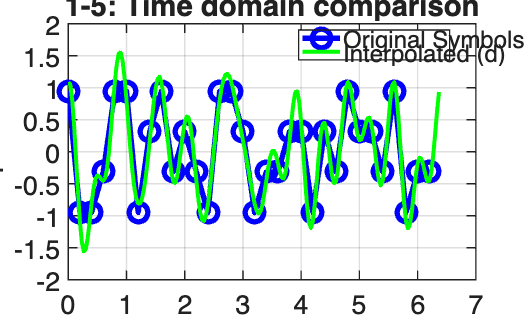

%5:
%plot the time domain
figure;
plot(t_symbols_b, symbols_b_real, 'bo-','LineWidth',2,'MarkerSize',7); hold on;
plot(t_symbols_c, real(symbols_d), 'g-','LineWidth',1.5);  % 平滑曲線
xlabel('Time (s)'); ylabel('Amplitude'); grid on;
legend('Original Symbols (b)','Interpolated (d)','Location','best');
title('1-5: Time domain comparison');

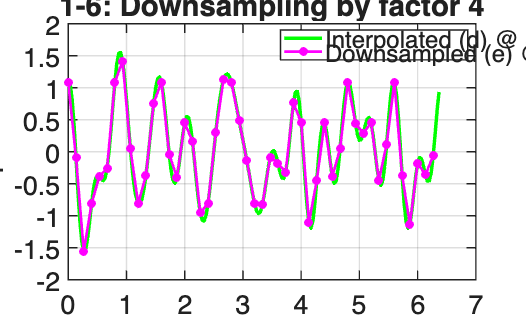

%6:
factor_int = f_s_TX / f_s_RX;%4
symbols_e = symbols_d(1:factor_int:end);%down sample
t_symbols_e = (0:length(symbols_e)-1).' / f_s_RX;%time axis for (e)

%plot the d(interp_signal) and e(down_sampling signal)
figure;
plot(t_symbols_c,  real(symbols_d), 'g-','LineWidth',1.3); hold on;
plot(t_symbols_e,  real(symbols_e),      'm.-','LineWidth',1.0,'MarkerSize',10);
grid on; xlabel('Time (s)'); ylabel('Amplitude');
legend('Interpolated (d) @ 30 Hz','Downsampled (e) @ 7.5 Hz','Location','best');
title('1-6: Downsampling by factor 4');

%7:

$\frac{f_s }{f_S^{\mathrm{RX}} }=\frac{5}{7\ldotp 5}=\frac{2}{3}$, Thus A = 2 and B = 3.

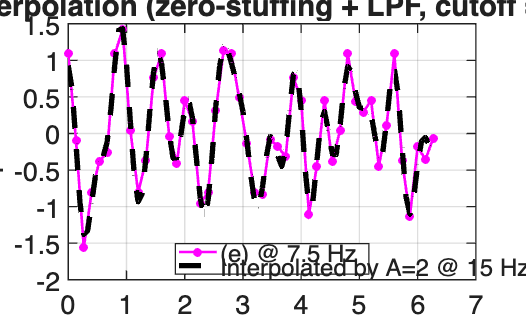

%8:
A = 2;
f_s_A   = f_s_RX * A;      % 15 Hz (after upsampling by 2)

% Zero-stuff upsampling
symbols_e_intA = zeros(length(symbols_e)*A,1);
symbols_e_intA(1:A:end) = symbols_e;

% Interpolation LPF: cutoff = f_s/2 = 2.5 Hz, normalized to Fs_A/2
Ntap  = 101;
cutoff_norm_A = (f_s/2) / (f_s_A/2);   % 2.5 / 7.5 = 1/3
hA = fir1(Ntap-1, cutoff_norm_A)*A;     % windowed-sinc LPF
symbols_f = conv(symbols_e_intA, hA, 'same');      % interpolated signal at 15 Hz
% Time axis
t_symbols_f   = (0:length(symbols_e_intA)-1).'   / f_s_A;  % (A): 15 Hz

% Plot time domain
figure;
plot(t_symbols_e,  real(symbols_e),      'm.-','LineWidth',1.0,'MarkerSize',10);
hold on;
plot(t_symbols_f, real(symbols_f), 'k--', 'LineWidth', 2);
grid on;
xlabel('Time (s)'); ylabel('Amplitude');
legend('(e) @ 7.5 Hz','Interpolated by A=2 @ 15 Hz','Location','best');
title('1-8: Interpolation (zero-stuffing + LPF, cutoff = 2.5 Hz)');

%9:

To avoid aliasing effect, $f_{\mathrm{cut}} \le \frac{F_{S,\mathrm{out}} }{2}=\frac{5}{2}=2\ldotp 5\mathrm{Hz}$ must be satisfied.

Thus the range of the decimator LPF is [-2.5, 2.5] Hz.

We use the a LPF with 1/3 Hz cutoff frequency in the interpolation, so the aliasing effect is already avoided.  Thus the LPF for the decimator is not necessary.

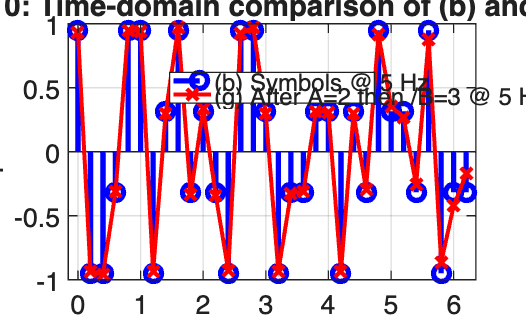

%10:
%downsampling by B
B = 3;
symbols_g = symbols_f(1:B:end);  % Now at 15/3 = 5 Hz

%time-axis
t_symbols_g = (0:length(symbols_g)-1).' / (f_s_A/B);
%plot
figure;
stem(t_symbols_b, symbols_b_real, 'bo-','LineWidth',2,'MarkerSize',6); hold on;
plot(t_symbols_g, real(symbols_g), 'rx-','LineWidth',1.5,'MarkerSize',6);
grid on; xlabel('Time (s)'); ylabel('Amplitude');
legend('(b) Symbols @ 5 Hz','(g) After A=2 then /B=3 @ 5 Hz','Location','best');
title('1-10: Time-domain comparison of (b) and (g)');

%11:
g_use = symbols_g(1:symbols_b_length);

rx_bits = qamdemod(g_use, 16, 'gray', 'UnitAveragePower', true, 'OutputType', 'bit');
tx_bits_use = bits(1:symbols_b_length*4);

% Bit errors
bit_errs = sum(rx_bits(:) ~= tx_bits_use(:));
BER = bit_errs / numel(tx_bits_use);
fprintf('1-11: Bit errors = %d / %d  (BER = %.4g)\n', bit_errs, numel(tx_bits_use), BER);

1-11: Bit errors = 0 / 128  (BER = 0)


# Part2

## Aliasing  in downsampling

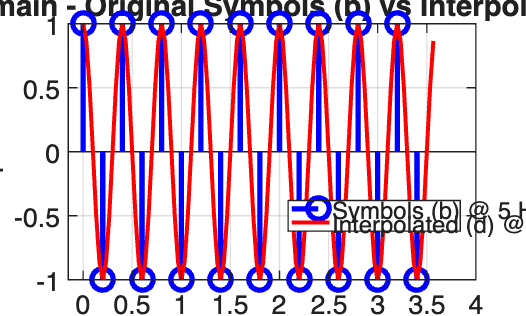

%1:
M_2 = 9;
tx_bits_pattern1 = [1,0,1,0,1,0,1,0,1,0,1,0,1,0,1,0,1,0];
symbols_b_2 = 2*tx_bits_pattern1 - 1;  % BPSK mapping
symbols_b_2 = symbols_b_2(:);  % Column vector
symbols_b_2_length = length(symbols_b_2); %18

% Time axis for symbols (b)
t_symbols_b_2 = (0:symbols_b_2_length-1).' / f_s;
%fft and freq axis for b
X_b_2 = fftshift(fft(symbols_b_2));
freq_b_2 = (-length(symbols_b_2)/2:length(symbols_b_2)/2-1) * f_s / length(symbols_b_2);

% Upsample by L=6 (insert zeros)
f_s_up = f_s * L;  % 30 Hz after upsampling
symbols_c_2 = zeros(symbols_b_2_length * L, 1);
symbols_c_2(1:L:end) = symbols_b_2;
X_c_2 = fftshift(fft(symbols_c_2)); 
freq_c_2 = (-length(symbols_c_2)/2:length(symbols_c_2)/2-1) * f_s_up / length(symbols_c_2);

% Time axis for upsampled signal (c)
t_symbols_c_2 = (0:length(symbols_c_2)-1).' / f_s_up;

% Interpolation filter: cutoff = f_s/2 = 2.5 Hz
cutoff_norm = (f_s/2) / (f_s_up/2);  % 2.5/15 = 1/6
h_interp = double(abs(freq_c_2) <= f_s/2) * L;
X_d_2 = X_c_2 .* h_interp(:);

symbols_d_2 = ifft(ifftshift(X_d_2))/2;
freq_d_2 = (-length(symbols_d_2)/2:length(symbols_d_2)/2-1) * f_s_up / length(symbols_d_2);

% Plot Q1: Time domain
figure('Name', 'Q1: Time Domain');
stem(t_symbols_b_2, real(symbols_b_2), 'bo-', 'LineWidth', 2, 'MarkerSize', 8); hold on;
plot(t_symbols_c_2, real(symbols_d_2), 'r-', 'LineWidth', 1.5);
grid on;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('2-1: Time Domain - Original Symbols (b) vs Interpolated Signal (d)');
legend('Symbols (b) @ 5 Hz', 'Interpolated (d) @ 30 Hz', 'Location', 'best');

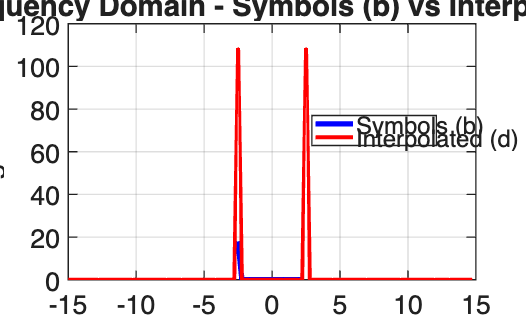

%2:
% Plot Q2: Frequency domain
figure;
plot(freq_b_2, abs(X_b_2), 'b-', 'LineWidth', 2); hold on;
plot(freq_d_2, abs(X_d_2), 'r-', 'LineWidth', 1.5);
xlim([-15 15]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('2-2: Frequency Domain - Symbols (b) vs Interpolated (d)');
legend('Symbols (b)', 'Interpolated (d)', 'Location', 'best');

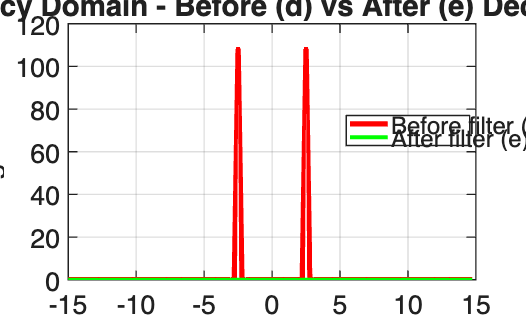

%3:
f_s_down = f_s_up / M_2;  % 3.333 Hz
f_cutoff_dec = f_s_down / 2;  % 1.667 Hz

% Apply decimation filter
H_dec = double(abs(freq_d_2) <= f_cutoff_dec);
X_e_2 = X_d_2 .* H_dec(:);

% IFFT of filtered signal (e)
symbols_e_2 = ifft(ifftshift(X_e_2), length(symbols_c_2));
freq_e_2 = freq_d_2;

% Plot Q3: Frequency domain comparison (d) vs (e)
figure;
plot(freq_d_2, abs(X_d_2), 'r-', 'LineWidth', 2); hold on;
plot(freq_e_2, abs(X_e_2), 'g-', 'LineWidth', 1.5);
xlim([-15 15]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('2-3: Frequency Domain - Before (d) vs After (e) Decimation Filter');
legend('Before filter (d)', 'After filter (e)', 'Location', 'best');

Observation and explanation: 輸出 Nyquist 只有 1.667 Hz，所以1.667–2.5 Hz的頻譜會被濾除。這樣的現象在這組交錯的 bit pattern更明顯，因為這樣交錯的序列有更高頻的成分．

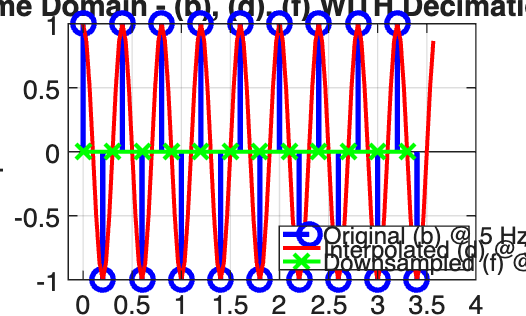

%4:
symbols_f_2 = symbols_e_2(1:M_2:end);
t_symbols_f_2 = (0:length(symbols_f_2)-1).' / f_s_down;

% Plot Q4: Time domain comparison (b), (d), and (f)
figure;
stem(t_symbols_b_2, real(symbols_b_2), 'bo-', 'LineWidth', 2, 'MarkerSize', 8); hold on;
plot(t_symbols_c_2, real(symbols_d_2), 'r-', 'LineWidth', 1.5);
plot(t_symbols_f_2, real(symbols_f_2), 'gx-', 'LineWidth', 1.5, 'MarkerSize', 8);
grid on;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('2-4: Time Domain - (b), (d), (f) WITH Decimation Filter');
legend('Original (b) @ 5 Hz', 'Interpolated (d) @ 30 Hz', 'Downsampled (f) @ 3.33 Hz', 'Location', 'best');

Observation and explanation: 在time domain看起來更明顯，因為濾波移除了訊號的主要頻率(高頻段)，所以看起來振幅頻率都很小．

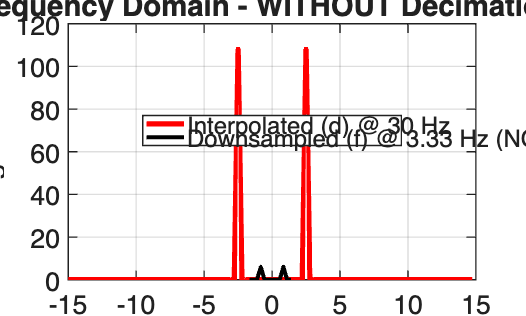

%5:
symbols_f_no_filter = symbols_d_2(1:M_2:end);
t_symbols_f_no_filter = (0:length(symbols_f_no_filter)-1).' / f_s_down;

% FFT of downsampled signal without filter
X_f_2_no_filter = fftshift(fft(symbols_f_no_filter, length(symbols_f_no_filter)));
freq_f_no_filter = (-length(symbols_f_no_filter)/2:length(symbols_f_no_filter)/2-1) * f_s_down / length(symbols_f_no_filter);

% Plot Q5: Frequency domain - WITH vs WITHOUT filter
figure('Name', 'Q5: Aliasing Effect - Frequency Domain');
plot(freq_d_2, abs(X_d_2), 'r-', 'LineWidth', 2); hold on;
plot(freq_f_no_filter, abs(X_f_2_no_filter), 'k-', 'LineWidth', 1.5);
xlim([-15 15]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('2-5: Frequency Domain - WITHOUT Decimation Filter');
legend('Interpolated (d) @ 30 Hz', 'Downsampled (f) @ 3.33 Hz (NO FILTER)', 'Location', 'best');

Observation and explanation: 可以看到頻譜沒有像之前一樣被濾掉，而是在中間長出一坨高峰．這是因為(d) 裡1.667–2.5 Hz的能量沒有先被拿掉，這段的能量大於Nyquist的1.667Hz.根據aliasing effect它會被折回 [0, 1.667] hz之內．

這個交錯 bit pattern 的主峰在 2.5 Hz，就被折到 ∣2.5−1×3.333∣ ≈ 0.833 Hz 左右，所以會以 f = 0.833為中央隆起，旁邊的圖可以驗證黑色中鋒的確在$\pm$0.833。

但黑色 (f) 的頻譜不是沒被濾掉，而是被折回來了，但是是錯的頻率成分。

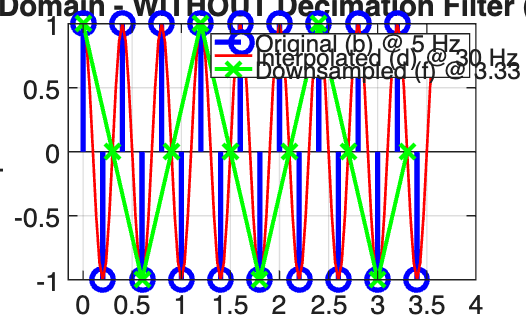

%6:
figure('Name', 'Q6: Time Domain WITHOUT Decimation Filter');
stem(t_symbols_b_2, real(symbols_b_2), 'bo-', 'LineWidth', 2, 'MarkerSize', 8); hold on;
plot(t_symbols_c_2, real(symbols_d_2), 'r-', 'LineWidth', 1);
plot(t_symbols_f_no_filter, real(symbols_f_no_filter), 'gx-', 'LineWidth', 1.5, 'MarkerSize', 8);
grid on;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('2-6: Time Domain - WITHOUT Decimation Filter (ALIASING)');
legend('Original (b) @ 5 Hz', 'Interpolated (d) @ 30 Hz', 'Downsampled (f) @ 3.33 Hz (NO FILTER)', 'Location', 'best');

Observation and explanation: 3.33 Hz < 5 Hz，違反取樣定理，所以高頻內容被折到低頻，產生較慢的起伏。跟第四題比起來看起來還有振幅，但這只是aliasing effect．因為它比較低頻，所以看起來追不上原來的sequence。

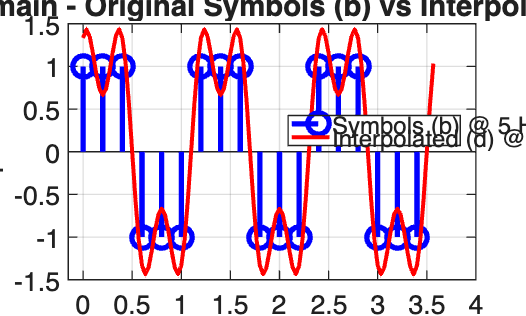

%7:
% Time axis for symbols (b)
tx_bits_pattern2 = [1,1,1,0,0,0,1,1,1,0,0,0,1,1,1,0,0,0];
symbols_b_3 = 2*tx_bits_pattern2 - 1;  % BPSK mapping
symbols_b_3 = symbols_b_3(:);  % Column vector
symbols_b_3_length = length(symbols_b_3); %18

% Time axis for symbols (b)
t_symbols_b_3 = (0:symbols_b_3_length-1).' / f_s;
X_b_3 = fftshift(fft(symbols_b_3));
freq_b_3 = (-length(symbols_b_3)/2:length(symbols_b_3)/2-1) * f_s / length(symbols_b_3);

% Upsample by L=6 (insert zeros)
symbols_c_3 = zeros(symbols_b_3_length * L, 1);
symbols_c_3(1:L:end) = symbols_b_3;
X_c_3 = fftshift(fft(symbols_c_3)); 
freq_c_3 = (-length(symbols_c_3)/2:length(symbols_c_3)/2-1) * f_s_up / length(symbols_c_3);

% Time axis for upsampled signal (c)
t_symbols_c_3 = (0:length(symbols_c_3)-1).' / f_s_up;
% Interpolation filter: cutoff = f_s/2 = 2.5 Hz
h_interp_2 = double(abs(freq_c_3) <= f_s/2) * L;
X_d_3 = X_c_3 .* h_interp_2(:);

symbols_d_3 = ifft(ifftshift(X_d_3));
freq_d_3 = (-length(symbols_d_3)/2:length(symbols_d_3)/2-1) * f_s_up / length(symbols_d_3);

% Plot Q1: Time domain
figure('Name', 'Q1: Time Domain');
stem(t_symbols_b_3, real(symbols_b_3), 'bo-', 'LineWidth', 2, 'MarkerSize', 8); hold on;
plot(t_symbols_c_3, real(symbols_d_3), 'r-', 'LineWidth', 1.5);
grid on;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('2-7: Time Domain - Original Symbols (b) vs Interpolated Signal (d)');
legend('Symbols (b) @ 5 Hz', 'Interpolated (d) @ 30 Hz', 'Location', 'best');

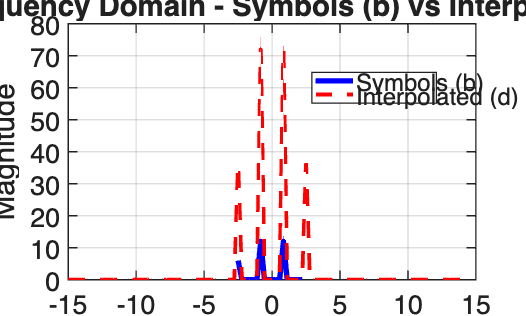

%8:
% Plot Q2: Frequency domain
figure;
plot(freq_b_3, abs(X_b_3), 'b-', 'LineWidth', 2); hold on;
plot(freq_d_3, abs(X_d_3), 'r--', 'LineWidth', 1.5);
xlim([-15 15]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('2-8: Frequency Domain - Symbols (b) vs Interpolated (d)');
legend('Symbols (b)', 'Interpolated (d)', 'Location', 'best');

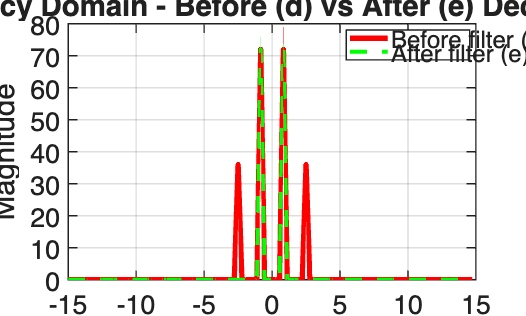

%9:
% Apply decimation filter
H_dec_2 = double(abs(freq_d_3) <= f_cutoff_dec);
X_e_3 = X_d_3 .* H_dec_2(:);

% IFFT of filtered signal (e)
symbols_e_3 = ifft(ifftshift(X_e_3), length(symbols_c_3));
freq_e_3 = freq_d_3;

% Plot Q3: Frequency domain comparison (d) vs (e)
figure;
plot(freq_d_3, abs(X_d_3), 'r-', 'LineWidth', 2); hold on;
plot(freq_e_3, abs(X_e_3), 'g--', 'LineWidth', 1.5);
xlim([-15 15]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('2-9: Frequency Domain - Before (d) vs After (e) Decimation Filter');
legend('Before filter (d)', 'After filter (e)', 'Location', 'best');

Observation and explanation: 跟(3)一樣，輸出 Nyquist 只有 1.667 Hz，所以1.667–2.5 Hz的頻譜會被濾除。但在這組比較連續的bit pattern中，因為連續的序列有更低頻的成分，所以更多頻譜被保留下來．

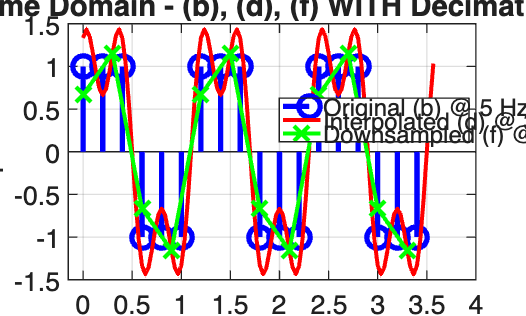

%10:
%4:
symbols_f_3 = symbols_e_3(1:M_2:end);
t_symbols_f_3 = (0:length(symbols_f_3)-1).' / f_s_down;

% Plot Q4: Time domain comparison (b), (d), and (f)
figure;
stem(t_symbols_b_3, real(symbols_b_3), 'bo-', 'LineWidth', 2, 'MarkerSize', 8); hold on;
plot(t_symbols_c_3, real(symbols_d_3), 'r-', 'LineWidth', 1.5);
plot(t_symbols_f_3, real(symbols_f_3), 'gx-', 'LineWidth', 1.5, 'MarkerSize', 8);
grid on;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('2-10: Time Domain - (b), (d), (f) WITH Decimation Filter');
legend('Original (b) @ 5 Hz', 'Interpolated (d) @ 30 Hz', 'Downsampled (f) @ 3.33 Hz', 'Location', 'best');

Observation and explanation: 因為更多頻譜被保留下來，所以downsampling完的信號有辦法大致保留原始信號，但在有轉折處的高頻地方依然會失真(這段序列太短了，如果更長的話就可以看到Gibb's effect的形狀)．

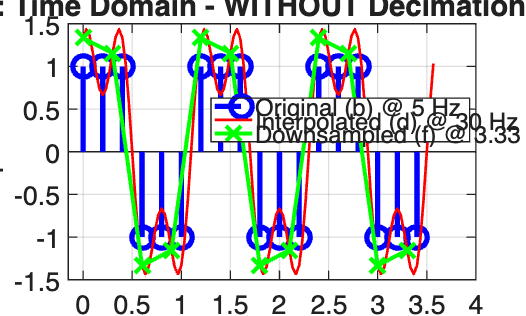

%11:
symbols_f_no_filter_2 = symbols_d_3(1:M_2:end);
t_symbols_f_no_filter_2 = (0:length(symbols_f_no_filter_2)-1).' / f_s_down;

figure('Name', 'Q6: Time Domain WITHOUT Decimation Filter');
stem(t_symbols_b_3, real(symbols_b_3), 'bo-', 'LineWidth', 2, 'MarkerSize', 8); hold on;
plot(t_symbols_c_3, real(symbols_d_3), 'r-', 'LineWidth', 1);
plot(t_symbols_f_no_filter_2, real(symbols_f_no_filter_2), 'gx-', 'LineWidth', 1.5, 'MarkerSize', 8);
grid on;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('2-11: Time Domain - WITHOUT Decimation Filter');
legend('Original (b) @ 5 Hz', 'Interpolated (d) @ 30 Hz', 'Downsampled (f) @ 3.33 Hz (NO FILTER)', 'Location', 'best');

Observation and explanation: Alaising effect 提供了更多低頻成分，所以downsampling完的信號表現甚至比用過Decimation filter的表現更好，更平滑了一點．

%12:

交錯 pattern：downsampling後的 (f) 有低頻的"假起伏"，全部來自aliasing effect．

交錯 pattern：輪廓較貼近原趨勢（還是會失真，但比交錯 pattern 好很多），aliasing effect影響較小．

可以猜測(6)的BER會明顯高於(11).

# Part3

## Squaring root cosine filter

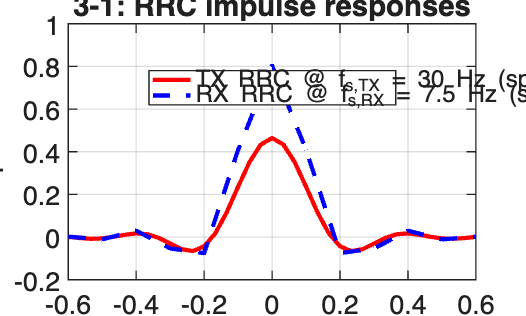

%1:
alpha   = 0.5;
spanSym = 6;
sps_tx  = f_s_TX / f_s;% = 6
f_s_RX_new  = 10;
sps_rx  = f_s_RX_new / f_s;% = 2

h_rrc_tx = rcosdesign(alpha, spanSym, sps_tx, 'sqrt');  % length = spanSym*sps_tx*2 + 1
h_rrc_rx = rcosdesign(alpha, spanSym, sps_rx, 'sqrt');  % length = spanSym*sps_rx*2 + 1

% time-axis(t = 0 in the middle)
t_rrc_tx = ((0:numel(h_rrc_tx)-1) - (numel(h_rrc_tx)-1)/2) / f_s_TX; % 秒
t_rrc_rx = ((0:numel(h_rrc_rx)-1) - (numel(h_rrc_rx)-1)/2) / f_s_RX_new; % 秒

% plot the time domain response for TX/RX RRC
figure;
plot(t_rrc_tx, h_rrc_tx, 'r-', 'LineWidth', 1.6); 
hold on;
plot(t_rrc_rx, h_rrc_rx, 'b--', 'LineWidth', 1.6);
grid on; 
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('3-1: RRC impulse responses', alpha, spanSym));
legend(sprintf('TX RRC @ f_{s,TX} = %g Hz (sps = %d)', f_s_TX, sps_tx),sprintf('RX RRC @ f_{s,RX} = %g Hz (sps = %d)' ...
    , f_s_RX, sps_rx),'Location','best');

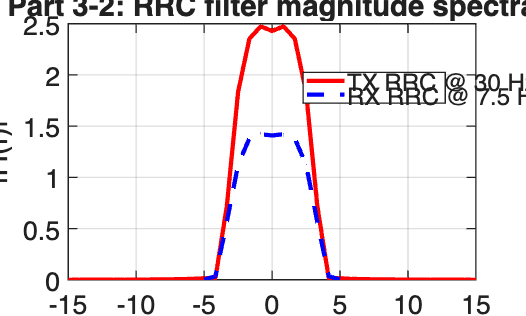

%2:
%TX RRC
Htx = fftshift(fft(h_rrc_tx));
fTX = linspace(-f_s_TX/2, f_s_TX/2,length(h_rrc_tx));
Htx_mag = abs(Htx);

%RX RRC
Hrx = fftshift(fft(h_rrc_rx));
fRX = linspace(-f_s_RX_new/2, f_s_RX_new/2,length(h_rrc_rx));
Hrx_mag = abs(Hrx);

% Plot spectrum
figure;
plot(fTX, Htx_mag, 'r-', 'LineWidth', 1.6); 
hold on;
plot(fRX, Hrx_mag, 'b--', 'LineWidth', 1.6);
grid on; 
xlabel('Frequency (Hz)'); ylabel('|H(f)|');
title('Part 3-2: RRC filter magnitude spectra');
legend(sprintf('TX RRC @ %g Hz', f_s_TX), sprintf('RX RRC @ %g Hz', f_s_RX), 'Location','best');
xlim([-15 15]);

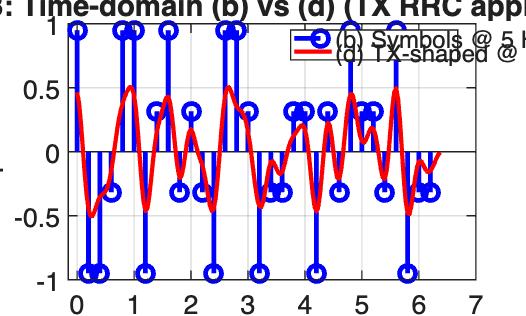

%3:
symbols_b   = Symbols(:);
% (c) upsampling to 30 hz
symbols_c_4   = upsample(symbols_b, sps_tx);
t_symbols_c_4 = (0:length(symbols_c_4)-1).' / f_s_TX;
% do fft for c
X_c_4 = fftshift(fft(symbols_c_4));
freq_c_4 = (-length(symbols_c_4)/2:length(symbols_c_4)/2-1) * f_s_TX / length(symbols_c_4);
h           = h_rrc_tx(:);                   % TX RRC (sqrt-raised-cosine)
Nh          = length(h);
Nlin        = length(symbols_c_4) + Nh - 1;                   % 線性卷積長度
Nfft        = 2^nextpow2(Nlin);              % 用較大的 FFT 長度避免循環捲積

Xc          = fft(symbols_c_4, Nfft);
Htx         = fft(h,         Nfft);
Yd          = Xc .* Htx;                     % 頻域相乘
d_full      = ifft(Yd);                      % 線性卷積結果（含群延遲）

% 取與 conv(...,'same') 對齊的片段（去掉群延遲 (Nh-1)/2）
Dtx         = floor((Nh-1)/2);               % 群延遲（樣本，@30 Hz）
idx_start   = Dtx + 1;
idx_end     = idx_start + length(symbols_c_4) - 1;
symbols_d_4   = d_full(idx_start:idx_end);     % (d) 與 (c) 等長，已對齊
              
% plot
figure;
stem(t_symbols_b, real(symbols_b), 'bo-','LineWidth',1.8,'MarkerSize',6); hold on;
plot(t_symbols_c_4, real(symbols_d_4), 'r-','LineWidth',1.6);
grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('3-3: Time-domain (b) vs (d) (TX RRC applied)');
legend('(b) Symbols @ 5 Hz','(d) TX-shaped @ 30 Hz','Location','best');

Observation: Yes, there is ISI effect.

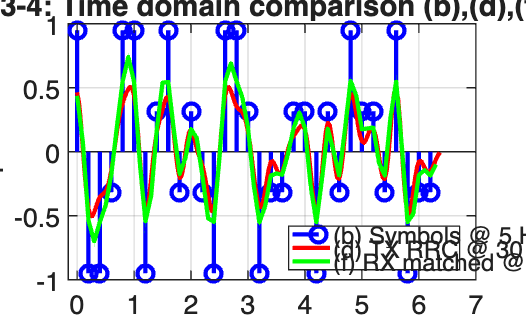

%4:
Mdec        = f_s_TX / f_s_RX_new; %3
symbols_e_4   = symbols_d_4(1:Mdec:end);
Ne          = length(symbols_e_4);
t_symbols_e_4 = (0:Ne-1).' / f_s_RX_new;           % 10 Hz grid

h_rx  = h_rrc_rx(:);
Nh_rx = length(h_rx);
Nlin2 = Ne + Nh_rx - 1;
Nfft2 = 2^nextpow2(Nlin2);

Xe    = fft(symbols_e_4, Nfft2);
Hrx   = fft(h_rx,      Nfft2);
Yf    = Xe .* Hrx;
f_full= ifft(Yf);

Drx         = (Nh_rx-1)/2;                   % group delay @10 Hz
symbols_f_4   = f_full(Drx+1 : Drx+Ne);        % align & same length as (e)
t_symbols_f_4 = t_symbols_e_4;
sps_rx       = f_s_RX_new / f_s;             % = 2 samples/symbol on RX grid
idx_sym_f    = 1:sps_rx:min(Ne, 1+(length(symbols_b)-1)*sps_rx);
%Plot
figure('Name','Part3-Q4: Time domain (b,d,f)');
stem(t_symbols_b, real(symbols_b), 'bo-','LineWidth',1.6,'MarkerSize',6); hold on;
plot(t_symbols_c_4, real(symbols_d_4), 'r-','LineWidth',1.6);
plot(t_symbols_f_4, real(symbols_f_4), 'g-','LineWidth',1.6);
grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('3-4: Time domain comparison (b),(d),(f)');
legend('(b) Symbols @ 5 Hz','(d) TX RRC @ 30 Hz','(f) RX matched @ 10 Hz','Location','best');

Observation: Yes, there is ISI effect.

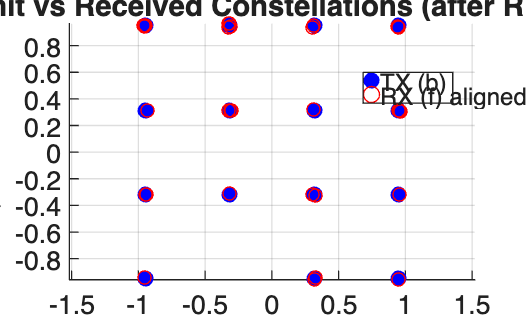

%5:
rx_syms = symbols_f_4(idx_sym_f);
tx_syms = Symbols(:);
Nmin    = min(length(rx_syms), length(tx_syms));
rx_syms = rx_syms(2:Nmin);
tx_syms = tx_syms(2:Nmin);%remove the transient state

k_cplx  = (rx_syms' * tx_syms) / (rx_syms' * rx_syms + eps);
rx_syms_aligned = k_cplx * rx_syms;

% 3) plot
figure('Name','Part 3-5: TX vs RX constellations');
scatter(real(tx_syms),imag(tx_syms),36, 'b', 'filled'); hold on;
scatter(real(rx_syms_aligned),imag(rx_syms_aligned), 24, 'r', 'o');
grid on; axis equal;
xlabel('In-Phase'); ylabel('Quadrature');
title('3-5: Transmit vs Received Constellations (after RRC & timing)');
legend('TX (b)', 'RX (f) aligned', 'Location', 'best');


%BER
rx_bits = qamdemod(rx_syms_aligned, 16, 'gray', 'UnitAveragePower', true, 'OutputType', 'bit');
tx_bits = qamdemod(tx_syms, 16, 'gray', 'UnitAveragePower', true, 'OutputType', 'bit');
BER = sum(rx_bits(:) ~= tx_bits(:)) / numel(tx_bits);
fprintf('3-5: The constellation are identical and the BER = %.4g', BER);

3-5: The constellation are identical and the BER = 0